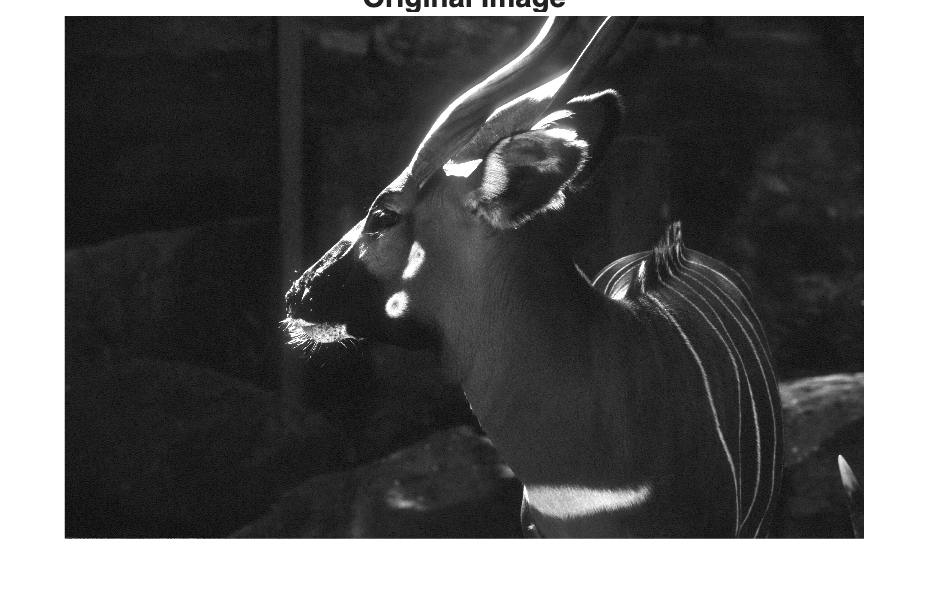

clear
% Discrete Cosine Transform compression
% See https://www.mathworks.com/help/images/discrete-cosine-transform.html
img = imread('theory/deer.pgm');
if size(img, 3) == 3
    img = rgb2gray(img);
end
img = im2double(img);
original_dims = size(img);

% IMPORTANT! Later we perform 8x8 transformations to the image with DCT
% matricies. This means that our image's dimensions need to be divisible by
% 8. This is why I cut the image by 1 row pixel and 3 column pixels.
img = img(1:original_dims(1)-1, 1:original_dims(2)-3);
img_dct = dct2(img);

% Perform 8x8 dct transformations
BlockSize = 8;
Block = [BlockSize BlockSize];
T = dctmtx(BlockSize);
dctProccess = @(block_struct) T * block_struct.data * T';
B = blockproc(img,Block,dctProccess);

% Use mask to disgard low energy coefficients.
mask_0 = zeros(BlockSize);
mask_1 = zeros(BlockSize);
mask_2 = zeros(BlockSize);

% Mask 1 keeps 1 coefficient.
mask_1(1, 1) = 1;

% Mask 2 keeps 3 coefficients
mask_2(1, 1) = 1;
mask_2(1, 2) = 1;
mask_2(2, 1) = 1;

% Apply masks
B0 = blockproc(B,Block,@(block_struct) mask_0 .* block_struct.data);
B1 = blockproc(B,Block,@(block_struct) mask_1 .* block_struct.data);
B2 = blockproc(B,Block,@(block_struct) mask_2 .* block_struct.data);

% Transform back to the spatial domain.
invdct = @(block_struct) T' * block_struct.data * T;
I0 = blockproc(B0,Block,invdct);
I1 = blockproc(B1,Block,invdct);
I2 = blockproc(B2,Block,invdct);

% Show original image.
figure;
imshow(img)
title("Original Image");


% Keeping 0 coefficients which yeilds a black screen.
figure;
imshow(I0)
fprintf("Size of image: %d %d", size(I0));

Size of image: 2640 4040

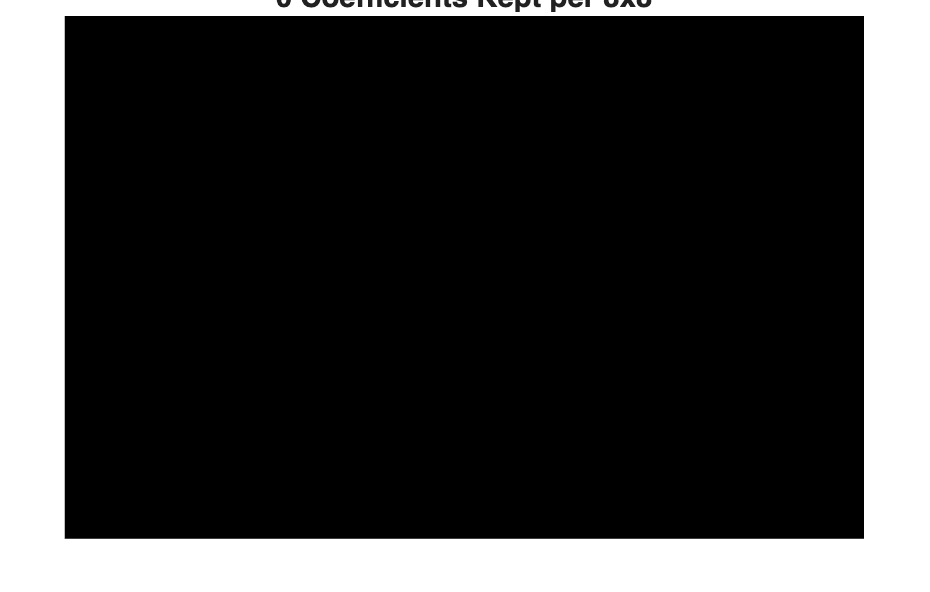

title("0 Coefficients Kept per 8x8");


% Keeping only 1 coefficient per 8x8 area. This results in a pretty good looking
% reconstructed image at face value, but edges of the deer are very
% pixelated if you zoom in.
figure;
imshow(I1)
fprintf("Size of image: %d %d", size(I1));

Size of image: 2640 4040

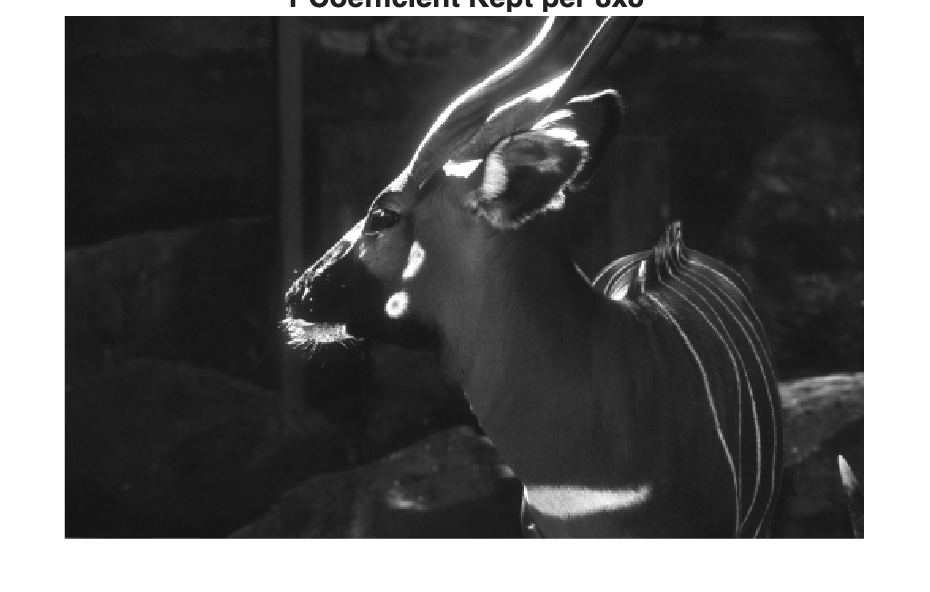

title("1 Coefficient Kept per 8x8");


% Keeping 3 coefficients per 8x8 area. Results are miles better than using
% a mask which keeps only 1 coefficient.
figure;
imshow(I2)
fprintf("Size of image: %d %d", size(I2));

Size of image: 2640 4040

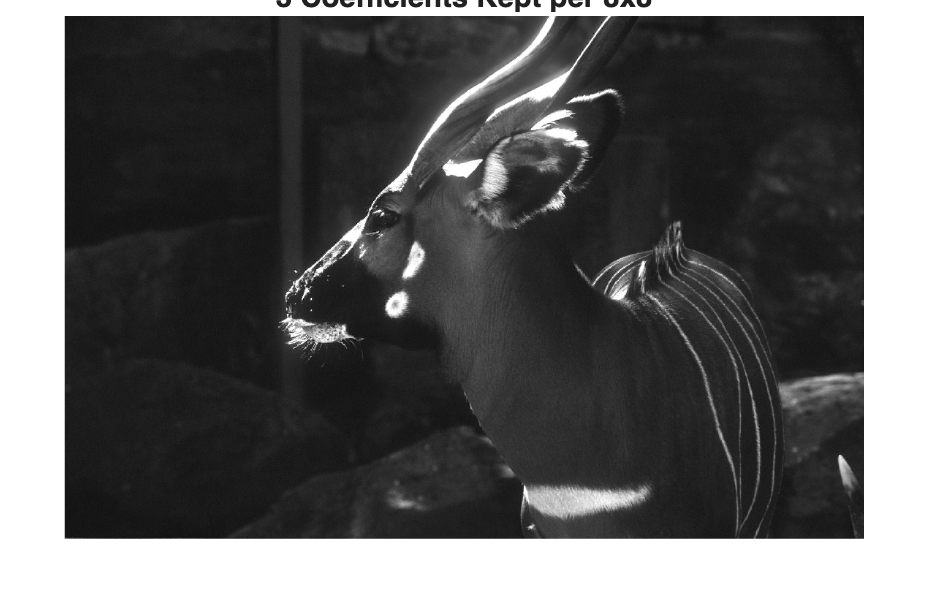

title("3 Coefficients Kept per 8x8");

% write an image and find how big it is after compression
imwrite(I2, 'my_compressed_image.jpg');
info = imfinfo('my_compressed_image.jpg');
disk_size_bytes = info.FileSize;
disk_size_kb = disk_size_bytes / 1024;
fprintf('The compressed image size on disk is %.2f KB\n', disk_size_kb);

The compressed image size on disk is 298.65 KB



% look at the original image for reference
og_info = imfinfo("theory/deer.pgm");
og_disk_size_bytes = og_info.FileSize;
og_disk_size_kb = og_disk_size_bytes / 1024;
fprintf('The original image size on disk is %.2f KB\n', og_disk_size_kb);

The original image size on disk is 10427.32 KB
